% 1. Define the experimental data
current = [-0.02, 0.15, 0.34, 0.57, 0.81, 1.04, 1.27, 1.50, 1.72, 1.94, 2.15]; % Current in Amperes
B_field_raw = [102, 660, 1386, 2213, 3105, 3943, 4806, 5654, 6489, 7280, 8067];

% Convert magnetic field to Tesla (scaling by 10^-4 as indicated in the header)
B_field = B_field_raw * 1e-4; 

% 2. Perform Linear Fitting (1st-degree polynomial)
% The model is B = a * I + b
p = polyfit(current, B_field, 1);
a = p(1); % Slope (dT/dA)
b = p(2); % Intercept (T)

% Generate finely spaced points for a smooth fitted line
I_fit = linspace(min(current), max(current), 100);
B_fit = polyval(p, I_fit);

% 3. Calculate R-squared value to evaluate the fit
B_fit_points = polyval(p, current);
SS_res = sum((B_field - B_fit_points).^2);      % Residual sum of squares
SS_tot = sum((B_field - mean(B_field)).^2);     % Total sum of squares
R_squared = 1 - (SS_res / SS_tot);

% Output the fitting parameters to the command window
fprintf('Linear Fit Equation: B = %.4e * I %+.4e\n', a, b);

Linear Fit Equation: B = 3.6866e-01 * I +1.2910e-02


fprintf('Goodness of fit (R^2): %.6f\n', R_squared);

Goodness of fit (R^2): 0.999945


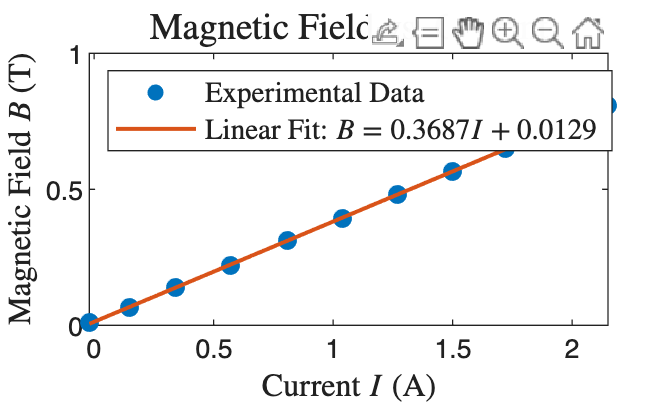


% 4. Visualization
figure('Name', 'Magnetic Field Linear Fit', 'Color', 'w');
hold on; grid off; box on;

% Plot experimental data as scatter points
scatter(current, B_field, 50, 'filled', 'MarkerFaceColor', '[0 0.4470 0.7410]', ...
    'DisplayName', 'Experimental Data');

% Plot the fitted line
plot(I_fit, B_fit, '-', 'Color', '[0.8500 0.3250 0.0980]', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Linear Fit: $B = %.4f I %+.4f$', a, b));

% Formatting aesthetics (using LaTeX interpreter for proper mathematical typography)
xlabel('Current $I$ (A)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Magnetic Field $B$ (T)', 'Interpreter', 'latex', 'FontSize', 12);
title('Magnetic Field vs. Current', 'Interpreter', 'latex', 'FontSize', 14);

% Configure legend
legend('Location', 'northwest', 'Interpreter', 'latex', 'FontSize', 11);

hold off;

% 1. 实验参数设定
% 注意：请将这里的 k_B 替换为你上一次磁场校准拟合得到的斜率 (T/A)
% 请将 L 替换为你的 MR3-2 样品的实际长度 (m)
k_B = 0.3687; % 示例：上一个图表中测得的磁场与电流比例系数 (T/A)
L = 0.0084;     % 示例：样品长度，假设为 2cm = 0.02m

% 2. 数据录入
% 零磁场下的基准角度 (MR3-2无磁场: 51度34分)
theta_0_deg = 51 + 34/60; 

% 倍频法数据 (电流A vs 角度(十进制))
I_doubling = [0.14, 0.36, 0.58, 0.80, 1.03, 1.26, 1.48, 1.70, 1.91, 2.12];
theta_doubling_deg = [49.8667, 47.4667, 45.0000, 42.5000, 39.9000, 37.1333, 34.8333, 32.3667, 29.9667, 27.7000];

% 消光法数据 (电流A vs 角度(十进制))
I_extinction = [2.13, 1.92, 1.70, 1.49, 1.27, 1.04, 0.82, 0.60, 0.37, 0.15];
theta_extinction_deg = [27.6667, 29.6333, 31.7333, 36.5333, 38.3000, 39.0000, 42.8667, 43.9667, 47.7000, 48.8333];

% 3. 数据处理：计算旋转角绝对值，并转换为弧度 (rad)
% \Delta\theta = \theta_0 - \theta
delta_theta_doubling_rad = (theta_0_deg - theta_doubling_deg) * (pi / 180);
delta_theta_extinction_rad = (theta_0_deg - theta_extinction_deg) * (pi / 180);

% 4. 线性拟合 (1阶多项式: y = m*x + c)
p_doubling = polyfit(I_doubling, delta_theta_doubling_rad, 1);
p_extinction = polyfit(I_extinction, delta_theta_extinction_rad, 1);

m_doubling = p_doubling(1); % 倍频法斜率
m_extinction = p_extinction(1); % 消光法斜率

% 计算 Verdet 常数 V_D = m / (k_B * L)
VD_doubling = m_doubling / (k_B * L);
VD_extinction = m_extinction / (k_B * L);

% 计算 R^2 以验证线性度
fit_doubling_vals = polyval(p_doubling, I_doubling);
R2_doubling = 1 - sum((delta_theta_doubling_rad - fit_doubling_vals).^2) / sum((delta_theta_doubling_rad - mean(delta_theta_doubling_rad)).^2);

fit_extinction_vals = polyval(p_extinction, I_extinction);
R2_extinction = 1 - sum((delta_theta_extinction_rad - fit_extinction_vals).^2) / sum((delta_theta_extinction_rad - mean(delta_theta_extinction_rad)).^2);

% 输出结果到命令行
fprintf('--- 倍频法拟合结果 ---\n');

--- 倍频法拟合结果 ---


fprintf('旋转角 vs 电流斜率 m = %.4e rad/A (R^2 = %.4f)\n', m_doubling, R2_doubling);

旋转角 vs 电流斜率 m = 1.9630e-01 rad/A (R^2 = 0.9999)


fprintf('Verdet 常数 V_D = %.2f rad/(T*m)\n\n', VD_doubling);

Verdet 常数 V_D = 63.38 rad/(T*m)




fprintf('--- 消光法拟合结果 ---\n');

--- 消光法拟合结果 ---


fprintf('旋转角 vs 电流斜率 m = %.4e rad/A (R^2 = %.4f)\n', m_extinction, R2_extinction);

旋转角 vs 电流斜率 m = 1.9057e-01 rad/A (R^2 = 0.9853)


fprintf('Verdet 常数 V_D = %.2f rad/(T*m)\n', VD_extinction);

Verdet 常数 V_D = 61.53 rad/(T*m)


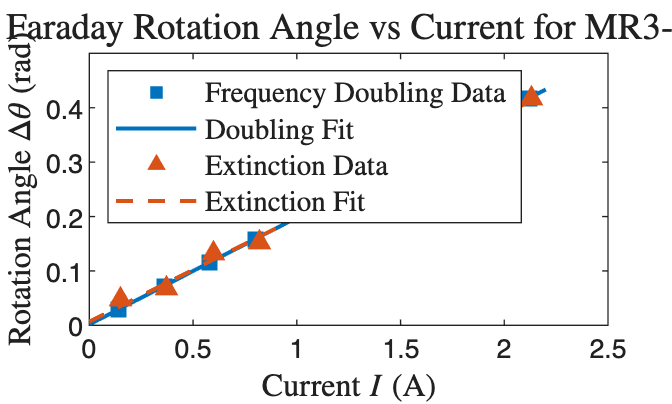


% 5. 图像绘制
figure('Name', 'Faraday Effect: Rotation Angle vs Current', 'Color', 'w');
hold on; grid off; box on;

% 绘制倍频法数据及拟合线
I_fit = linspace(0, 2.2, 100);
scatter(I_doubling, delta_theta_doubling_rad, 60, 's', 'filled', 'MarkerFaceColor', '[0 0.4470 0.7410]', 'DisplayName', 'Frequency Doubling Data');
plot(I_fit, polyval(p_doubling, I_fit), '-', 'Color', '[0 0.4470 0.7410]', 'LineWidth', 1.5, 'DisplayName', 'Doubling Fit');

% 绘制消光法数据及拟合线
scatter(I_extinction, delta_theta_extinction_rad, 60, '^', 'filled', 'MarkerFaceColor', '[0.8500 0.3250 0.0980]', 'DisplayName', 'Extinction Data');
plot(I_fit, polyval(p_extinction, I_fit), '--', 'Color', '[0.8500 0.3250 0.0980]', 'LineWidth', 1.5, 'DisplayName', 'Extinction Fit');

% 设置图像格式 (严格使用 LaTeX 渲染器)
xlabel('Current $I$ (A)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Rotation Angle $\Delta\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 12);
title('Faraday Rotation Angle vs Current for MR3-2', 'Interpreter', 'latex', 'FontSize', 14);
legend('Location', 'northwest', 'Interpreter', 'latex', 'FontSize', 11);

hold off;

% --- 1. 磁场校准参数 (根据你的第一张图数据计算) ---
I_calib = [-0.02, 0.15, 0.34, 0.57, 0.81, 1.04, 1.27, 1.50, 1.72, 1.94, 2.15];
B_calib_raw = [102, 660, 1386, 2213, 3105, 3943, 4806, 5654, 6489, 7280, 8067];
B_calib = B_calib_raw * 1e-4; % 转换为 Tesla (T)

% 拟合出 B 与 I 的关系: B = k_B * I + B_0
p_calib = polyfit(I_calib, B_calib, 1);
k_B = p_calib(1); 
B_0 = p_calib(2);

% --- 2. 实验参数与数据录入 (根据你的第二张图) ---
L = 0.0084; % ⚠️ 样品长度 (单位：m)，请根据你的实验讲义实际数值修改 (此处假设为2cm)
theta_0_deg = 51 + 34/60; % 无磁场下的基准角度

% 倍频法数据 (电流A vs 测量角度)
I_doubling = [0.14, 0.36, 0.58, 0.80, 1.03, 1.26, 1.48, 1.70, 1.91, 2.12];
theta_doubling_deg = [49.8667, 47.4667, 45.0000, 42.5000, 39.9000, 37.1333, 34.8333, 32.3667, 29.9667, 27.7000];

% 消光法数据 (电流A vs 测量角度)
I_extinction = [2.13, 1.92, 1.70, 1.49, 1.27, 1.04, 0.82, 0.60, 0.37, 0.15];
theta_extinction_deg = [27.6667, 29.6333, 31.7333, 36.5333, 38.3000, 39.0000, 42.8667, 43.9667, 47.7000, 48.8333];

% --- 3. 数据转换与处理 ---
% 将电流 I 换算为对应的磁场 B (单位: T)
B_doubling = k_B * I_doubling + B_0;
B_extinction = k_B * I_extinction + B_0;

% 计算偏振面旋转净角度并转换为弧度 (rad)
delta_theta_doubling_rad = (theta_0_deg - theta_doubling_deg) * (pi / 180);
delta_theta_extinction_rad = (theta_0_deg - theta_extinction_deg) * (pi / 180);

% --- 4. 线性拟合 (1阶多项式: \Delta\theta = m * B + c) ---
p_doubling = polyfit(B_doubling, delta_theta_doubling_rad, 1);
p_extinction = polyfit(B_extinction, delta_theta_extinction_rad, 1);

m_doubling = p_doubling(1); % 倍频法斜率 m = V_D * L
m_extinction = p_extinction(1); % 消光法斜率

% 直接由斜率计算 Verdet 常数 V_D = m / L
VD_doubling = m_doubling / L;
VD_extinction = m_extinction / L;

% 终端输出计算结果
fprintf('--- 第一步: 磁场校准关系 ---\n');

--- 第一步: 磁场校准关系 ---


fprintf('B(I) = %.4f * I %+.4f (T)\n\n', k_B, B_0);

B(I) = 0.3687 * I +0.0129 (T)




fprintf('--- 第二步: 倍频法拟合结果 ---\n');

--- 第二步: 倍频法拟合结果 ---


fprintf('Theta-B 斜率 m = %.4f rad/T\n', m_doubling);

Theta-B 斜率 m = 0.5325 rad/T


fprintf('Verdet 常数 V_D = %.2f rad/(T*m)\n\n', VD_doubling);

Verdet 常数 V_D = 63.39 rad/(T*m)




fprintf('--- 第三步: 消光法拟合结果 ---\n');

--- 第三步: 消光法拟合结果 ---


fprintf('Theta-B 斜率 m = %.4f rad/T\n', m_extinction);

Theta-B 斜率 m = 0.5169 rad/T


fprintf('Verdet 常数 V_D = %.2f rad/(T*m)\n', VD_extinction);

Verdet 常数 V_D = 61.54 rad/(T*m)


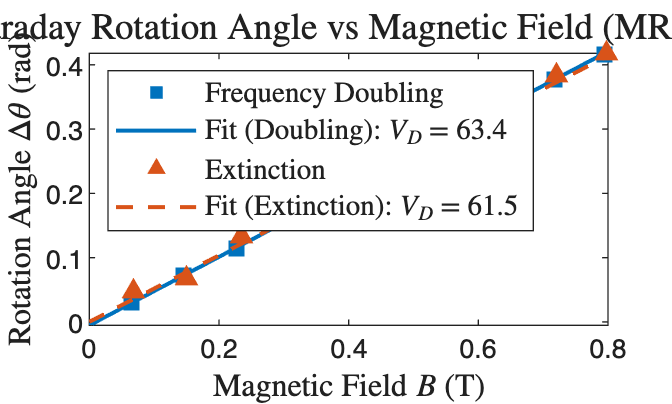


% --- 5. 图像绘制 ---
figure('Name', 'Faraday Effect: Rotation Angle vs Magnetic Field', 'Color', 'w');
hold on; grid off; box on;

% 生成平滑拟合线的数据点
B_fit_doubling = linspace(0, max(B_doubling), 100);
B_fit_extinction = linspace(0, max(B_extinction), 100);

% 绘制倍频法
scatter(B_doubling, delta_theta_doubling_rad, 60, 's', 'filled', 'MarkerFaceColor', '[0 0.4470 0.7410]', 'DisplayName', 'Frequency Doubling');
plot(B_fit_doubling, polyval(p_doubling, B_fit_doubling), '-', 'Color', '[0 0.4470 0.7410]', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Fit (Doubling): $V_D$ = %.1f', VD_doubling));

% 绘制消光法
scatter(B_extinction, delta_theta_extinction_rad, 60, '^', 'filled', 'MarkerFaceColor', '[0.8500 0.3250 0.0980]', 'DisplayName', 'Extinction');
plot(B_fit_extinction, polyval(p_extinction, B_fit_extinction), '--', 'Color', '[0.8500 0.3250 0.0980]', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Fit (Extinction): $V_D$ = %.1f', VD_extinction));

% 设置图像格式 (LaTeX 渲染器确保符号美观)
xlabel('Magnetic Field $B$ (T)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Rotation Angle $\Delta\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 12);
title('Faraday Rotation Angle vs Magnetic Field (MR3-2)', 'Interpreter', 'latex', 'FontSize', 14);
legend('Location', 'northwest', 'Interpreter', 'latex', 'FontSize', 11);

hold off;

% =========================================================================
% 法拉第效应实验数据处理：ZF7 玻璃 (升程与降程对比)
% =========================================================================

% --- 1. 磁场校准关系 (B vs I) ---
% 使用之前的校准数据建立 B(I) 映射
I_calib = [-0.02, 0.15, 0.34, 0.57, 0.81, 1.04, 1.27, 1.50, 1.72, 1.94, 2.15];
B_calib_raw = [102, 660, 1386, 2213, 3105, 3943, 4806, 5654, 6489, 7280, 8067];
B_calib = B_calib_raw * 1e-4; % 转换为 Tesla (T)

p_calib = polyfit(I_calib, B_calib, 1);
k_B = p_calib(1); 
B_0 = p_calib(2);

% --- 2. ZF7 实验参数与数据录入 ---
L = 0.02; % ⚠️ 样品长度 (单位：m)，请根据讲义核实并修改
theta_0_deg = 52 + 20/60; % ZF7无磁场基准角度 (52.3333度)

% 升程数据 (电流增大)
I_inc = [0.15, 0.38, 0.62, 0.84, 1.05, 1.28, 1.51, 1.73, 1.94, 2.15];
theta_inc_deg = [52.9667, 53.4333, 54.0000, 54.8000, 55.0333, 55.6333, 56.1667, 56.8000, 57.2667, 57.9667];

% 降程数据 (电流减小)
I_dec = [1.94, 1.71, 1.50, 1.27, 1.04, 0.83, 0.60, 0.37, 0.15];
theta_dec_deg = [57.3000, 56.8000, 56.2333, 55.8333, 55.1000, 54.5333, 54.0333, 53.4333, 52.9000];

% --- 3. 数据转换与处理 ---
% 将电流转换为磁场 B (T)
B_inc = k_B * I_inc + B_0;
B_dec = k_B * I_dec + B_0;

% 计算偏转角 (注意 ZF7 是角度增大，所以用 theta - theta_0) 并转为弧度
delta_theta_inc_rad = (theta_inc_deg - theta_0_deg) * (pi / 180);
delta_theta_dec_rad = (theta_dec_deg - theta_0_deg) * (pi / 180);

% --- 4. 线性拟合 ---
p_inc = polyfit(B_inc, delta_theta_inc_rad, 1);
p_dec = polyfit(B_dec, delta_theta_dec_rad, 1);

m_inc = p_inc(1); % 升程斜率
m_dec = p_dec(1); % 降程斜率

% 计算 Verdet 常数 V_D = m / L
VD_inc = m_inc / L;
VD_dec = m_dec / L;

% 计算平均 Verdet 常数 (消除磁滞和机械回程误差的严谨做法)
VD_mean = (VD_inc + VD_dec) / 2;

% 输出结果
fprintf('--- ZF7 法拉第效应拟合结果 ---\n');

--- ZF7 法拉第效应拟合结果 ---


fprintf('升程 (电流增大) V_D = %.2f rad/(T*m)\n', VD_inc);

升程 (电流增大) V_D = 5.84 rad/(T*m)


fprintf('降程 (电流减小) V_D = %.2f rad/(T*m)\n', VD_dec);

降程 (电流减小) V_D = 5.89 rad/(T*m)


fprintf('平均 Verdet 常数 V_D_mean = %.2f rad/(T*m)\n\n', VD_mean);

平均 Verdet 常数 V_D_mean = 5.86 rad/(T*m)



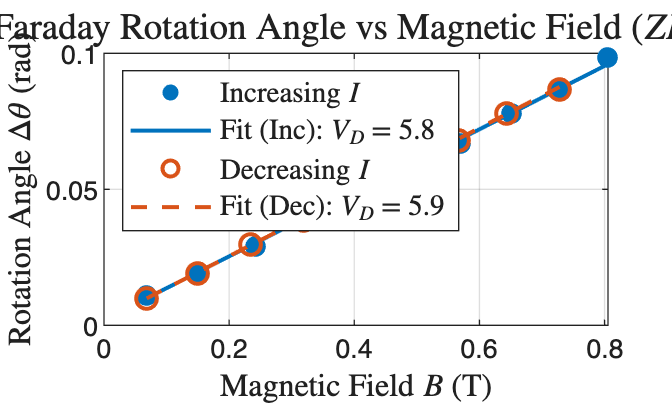


% --- 5. 图像绘制 ---
figure('Name', 'Faraday Effect: ZF7 Hysteresis Check', 'Color', 'w');
hold on; grid on; box on;

% 生成平滑的拟合线
B_fit_inc = linspace(min(B_inc), max(B_inc), 100);
B_fit_dec = linspace(min(B_dec), max(B_dec), 100);

% 绘制升程 (Increasing)
scatter(B_inc, delta_theta_inc_rad, 60, 'o', 'filled', 'MarkerFaceColor', '[0 0.4470 0.7410]', 'DisplayName', 'Increasing $I$');
plot(B_fit_inc, polyval(p_inc, B_fit_inc), '-', 'Color', '[0 0.4470 0.7410]', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Fit (Inc): $V_D$ = %.1f', VD_inc));

% 绘制降程 (Decreasing) - 使用空心标记以示区分
scatter(B_dec, delta_theta_dec_rad, 60, 'o', 'MarkerEdgeColor', '[0.8500 0.3250 0.0980]', 'LineWidth', 1.5, 'DisplayName', 'Decreasing $I$');
plot(B_fit_dec, polyval(p_dec, B_fit_dec), '--', 'Color', '[0.8500 0.3250 0.0980]', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Fit (Dec): $V_D$ = %.1f', VD_dec));

% 图像格式化 (使用 LaTeX)
xlabel('Magnetic Field $B$ (T)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Rotation Angle $\Delta\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 12);
title('Faraday Rotation Angle vs Magnetic Field ($ZF7$)', 'Interpreter', 'latex', 'FontSize', 14);
legend('Location', 'northwest', 'Interpreter', 'latex', 'FontSize', 11);

hold off;

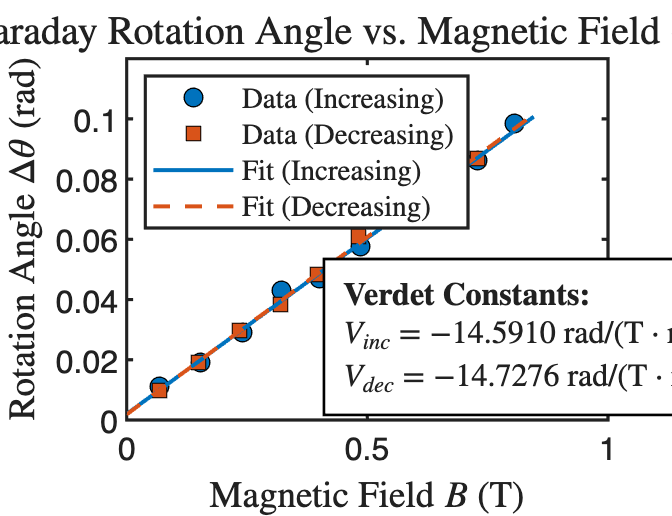

% =========================================================================
% 第一部分：数据录入与拟合 (使用 ZF7 的实验数据)
% =========================================================================

% 1. 磁场校准参数
I_calib = [-0.02, 0.15, 0.34, 0.57, 0.81, 1.04, 1.27, 1.50, 1.72, 1.94, 2.15];
B_calib = [102, 660, 1386, 2213, 3105, 3943, 4806, 5654, 6489, 7280, 8067] * 1e-4; 
p_calib = polyfit(I_calib, B_calib, 1);
k_B = p_calib(1); 
B_0 = p_calib(2);

% 2. ZF7 实验数据
L = 0.008; % 样品长度 (m)
theta_0_deg = 52 + 20/60; 

% 升程数据
I_inc = [0.15, 0.38, 0.62, 0.84, 1.05, 1.28, 1.51, 1.73, 1.94, 2.15];
theta_inc_deg = [52.9667, 53.4333, 54.0000, 54.8000, 55.0333, 55.6333, 56.1667, 56.8000, 57.2667, 57.9667];
B_inc = k_B * I_inc + B_0;
delta_theta_inc_rad = (theta_inc_deg - theta_0_deg) * (pi / 180);
p_inc = polyfit(B_inc, delta_theta_inc_rad, 1);
VD_inc = -p_inc(1) / L; % 升程费尔德常数

% 降程数据
I_dec = [1.94, 1.71, 1.50, 1.27, 1.04, 0.83, 0.60, 0.37, 0.15];
theta_dec_deg = [57.3000, 56.8000, 56.2333, 55.8333, 55.1000, 54.5333, 54.0333, 53.4333, 52.9000];
B_dec = k_B * I_dec + B_0;
delta_theta_dec_rad = (theta_dec_deg - theta_0_deg) * (pi / 180);
p_dec = polyfit(B_dec, delta_theta_dec_rad, 1);
VD_dec = -p_dec(1) / L; % 降程费尔德常数

% =========================================================================
% 第二部分：绘制实验报告标准图表
% =========================================================================

% 创建图形窗口
f = figure('Name', 'Faraday Effect Hysteresis', 'Color', 'w', 'Position', [150, 150, 650, 500]);
ax = axes('Parent', f);
hold(ax, 'on'); grid(ax, 'off'); box(ax, 'on');
ax.LineWidth = 1.2;
ax.FontSize = 12;

% 1. 绘制实验数据点 (散点)
plot(ax, B_inc, delta_theta_inc_rad, 'o', 'MarkerSize', 7, ...
    'MarkerFaceColor', '[0 0.4470 0.7410]', 'MarkerEdgeColor', 'k', ...
    'DisplayName', 'Data (Increasing)');
plot(ax, B_dec, delta_theta_dec_rad, 's', 'MarkerSize', 7, ...
    'MarkerFaceColor', '[0.8500 0.3250 0.0980]', 'MarkerEdgeColor', 'k', ...
    'DisplayName', 'Data (Decreasing)');

% 2. 绘制拟合直线
B_fit = linspace(0, max(B_inc)*1.05, 100);
plot(ax, B_fit, polyval(p_inc, B_fit), '-', 'Color', '[0 0.4470 0.7410]', ...
    'LineWidth', 1.5, 'DisplayName', 'Fit (Increasing)');
plot(ax, B_fit, polyval(p_dec, B_fit), '--', 'Color', '[0.8500 0.3250 0.0980]', ...
    'LineWidth', 1.5, 'DisplayName', 'Fit (Decreasing)');

% 3. 设置坐标轴标签和标题 (使用 LaTeX)
xlabel(ax, 'Magnetic Field $B$ (T)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel(ax, 'Rotation Angle $\Delta\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 14);
title(ax, 'Faraday Rotation Angle vs. Magnetic Field (ZF7)', 'Interpreter', 'latex', 'FontSize', 15);

% 4. 添加图例
legend(ax, 'Location', 'northwest', 'Interpreter', 'latex', 'FontSize', 11);

% 5. 在图中添加计算结果文本框 (显示拟合出的费尔德常数)
% 使用 LaTeX 语法排版多行公式
text_str = {
    '\textbf{Verdet Constants:}', ...
    sprintf('$V_{inc} = %.4f$ rad/(T$\\cdot$m)', VD_inc), ...
    sprintf('$V_{dec} = %.4f$ rad/(T$\\cdot$m)', VD_dec)
};

% 根据数据范围自动选择合适的文本框位置 (右下角偏上一点)
x_pos = max(B_inc) * 0.55;
y_pos = min(delta_theta_dec_rad) + (max(delta_theta_inc_rad) - min(delta_theta_dec_rad)) * 0.2;

text(ax, x_pos, y_pos, text_str, 'Interpreter', 'latex', 'FontSize', 12, ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'Margin', 6, 'LineWidth', 1);

hold(ax, 'off');

% =========================================================================
% 法拉第效应实验数据处理：石英 (Quartz) - 适用于 Live Script
% =========================================================================

% --- 1. 磁场校准关系 (沿用之前的校准数据建立 B(I) 映射) ---
I_calib = [-0.02, 0.15, 0.34, 0.57, 0.81, 1.04, 1.27, 1.50, 1.72, 1.94, 2.15];
B_calib_raw = [102, 660, 1386, 2213, 3105, 3943, 4806, 5654, 6489, 7280, 8067];
B_calib = B_calib_raw * 1e-4; % 转换为 Tesla (T)

p_calib = polyfit(I_calib, B_calib, 1);
k_B = p_calib(1); 
B_0 = p_calib(2);

% --- 2. 石英实验参数与数据录入 ---
L = 0.004; % ⚠️ 石英样品长度 (单位：m)，请务必核实你的实验讲义并修改
theta_0_deg = 306.8; % 石英无磁场基准角度

% 石英测量数据
I_quartz = [0.15, 0.37, 0.60, 0.82, 1.05, 1.27, 1.50, 1.71, 1.92, 2.14];
theta_quartz_deg = [306.8666667, 306.9333333, 306.9666667, 306.9833333, 307.0000000, ...
                    307.0333333, 307.1333333, 307.2000000, 307.2666667, 307.4000000];

% --- 3. 数据转换与处理 ---
% 将电流 I 转换为磁场 B (T)
B_quartz = k_B * I_quartz + B_0;

% 计算偏转角变化量 (角度增大，使用 theta - theta_0)，并转换为弧度 (rad)
delta_theta_quartz_rad = (theta_quartz_deg - theta_0_deg) * (pi / 180);

% --- 4. 线性拟合 ---
% 拟合多项式: \Delta\theta = m * B + c
p_quartz = polyfit(B_quartz, delta_theta_quartz_rad, 1);
m_quartz = p_quartz(1); % 斜率 m = V_D * L
c_quartz = p_quartz(2); % 截距

% 计算 Verdet 常数 V_D = m / L
VD_quartz = -m_quartz / L;

% 计算 R^2 以评估拟合优度 (考虑到石英变化微弱，测量误差影响可能较大)
fit_quartz_vals = polyval(p_quartz, B_quartz);
SS_res = sum((delta_theta_quartz_rad - fit_quartz_vals).^2);
SS_tot = sum((delta_theta_quartz_rad - mean(delta_theta_quartz_rad)).^2);
R2_quartz = 1 - (SS_res / SS_tot);

% 在命令窗口 (或 Live Script 输出区) 打印结果
fprintf('--- 石英 (Quartz) 拟合结果 ---\n');

--- 石英 (Quartz) 拟合结果 ---


fprintf('Theta-B 斜率 m = %.4e rad/T\n', m_quartz);

Theta-B 斜率 m = 1.1339e-02 rad/T


fprintf('线性拟合 R^2 = %.4f\n', R2_quartz);

线性拟合 R^2 = 0.9218


fprintf('Verdet 常数 V_D = %.4f rad/(T*m)\n\n', VD_quartz);

Verdet 常数 V_D = -2.8349 rad/(T*m)



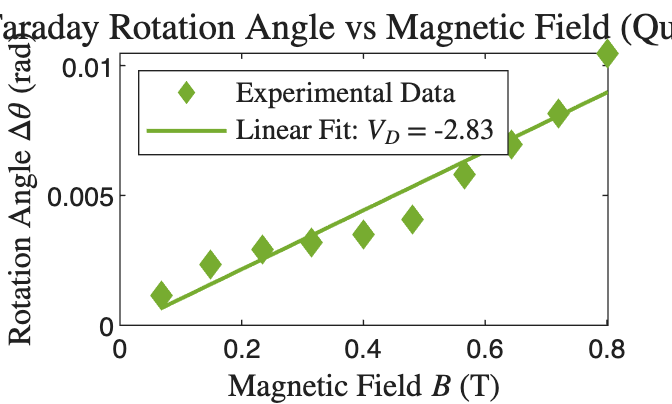


% --- 5. 图像绘制 ---
figure('Name', 'Faraday Effect: Quartz', 'Color', 'w');
hold on; grid off; box on;

% 绘制实验散点
scatter(B_quartz, delta_theta_quartz_rad, 60, 'd', 'filled', ...
    'MarkerFaceColor', '[0.4660 0.6740 0.1880]', 'DisplayName', 'Experimental Data');

% 绘制拟合直线
B_fit = linspace(min(B_quartz), max(B_quartz), 100);
theta_fit = polyval(p_quartz, B_fit);
plot(B_fit, theta_fit, '-', 'Color', '[0.4660 0.6740 0.1880]', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Linear Fit: $V_D$ = %.2f', VD_quartz));

% 设置图像格式 (LaTeX 渲染)
xlabel('Magnetic Field $B$ (T)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Rotation Angle $\Delta\theta$ (rad)', 'Interpreter', 'latex', 'FontSize', 12);
title('Faraday Rotation Angle vs Magnetic Field (Quartz)', 'Interpreter', 'latex', 'FontSize', 14);
legend('Location', 'northwest', 'Interpreter', 'latex', 'FontSize', 11);

hold off;